clc
clear variables
images_path = "D:\GMIS_DataSet\MultiExposure\Set_507"

images_path = "D:\GMIS_DataSet\MultiExposure\Set_507"

ds = imageDatastore(images_path);
exiftoolPath = "C:\exiftoolgui\exiftool.exe";

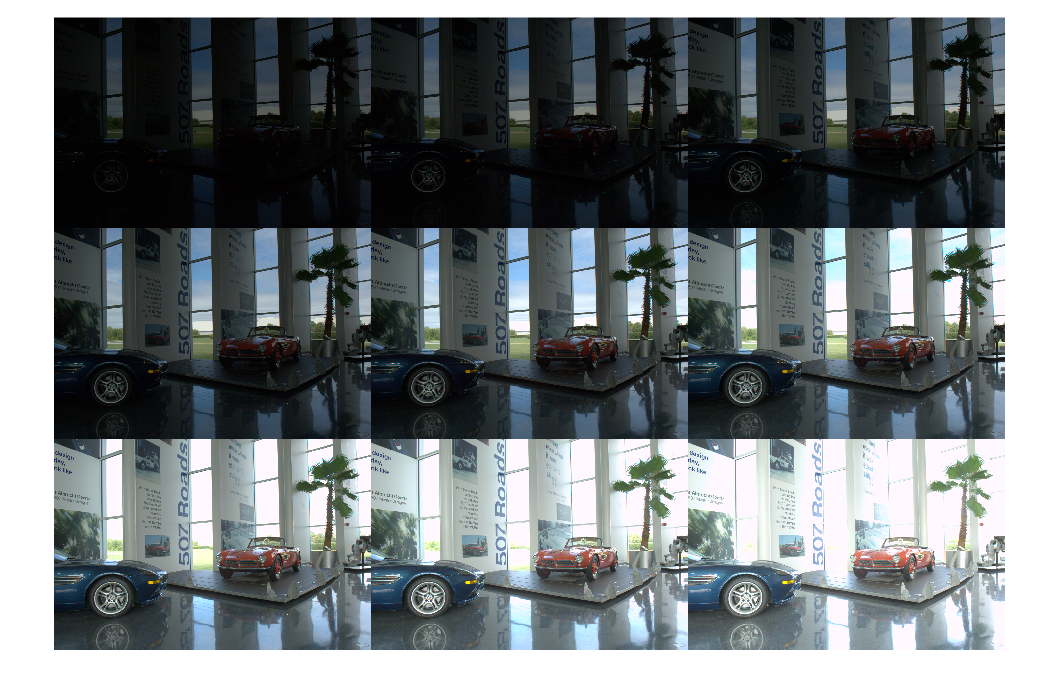

montage(ds)

noFiles = numel(ds.Files);

expTimes = zeros(1, noFiles);
for f = 1: noFiles
    command = sprintf('"%s" -ExposureTime -b "%s"', exiftoolPath, ds.Files{f});
    [status, cmdout] = system(command);
    if status == 0
        words = strsplit(cmdout);
        lastWord = words{end};
        exposureTime = str2double(lastWord);
        expTimes(f) = exposureTime;
        fprintf('The exposure time is %f seconds.\n', exposureTime);
    else
        fprintf('Error reading EXIF data: %s\n', cmdout);
    end
end

The exposure time is 0.001563 seconds.
The exposure time is 0.003125 seconds.
The exposure time is 0.006250 seconds.
The exposure time is 0.012500 seconds.
The exposure time is 0.025000 seconds.
The exposure time is 0.050000 seconds.
The exposure time is 0.100000 seconds.
The exposure time is 0.200000 seconds.
The exposure time is 0.400000 seconds.


HDR = makehdr(ds, 'ExposureValues',expTimes);

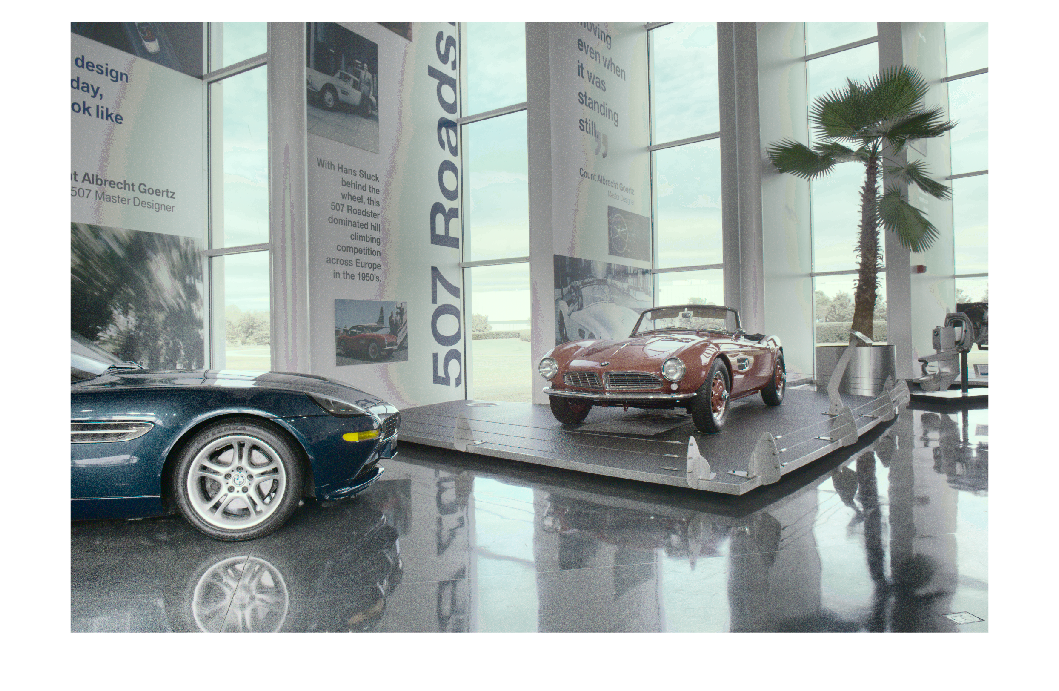

rgb = tonemap(HDR);
imshow(rgb)

xlim([1 2157])
ylim([1 1435])

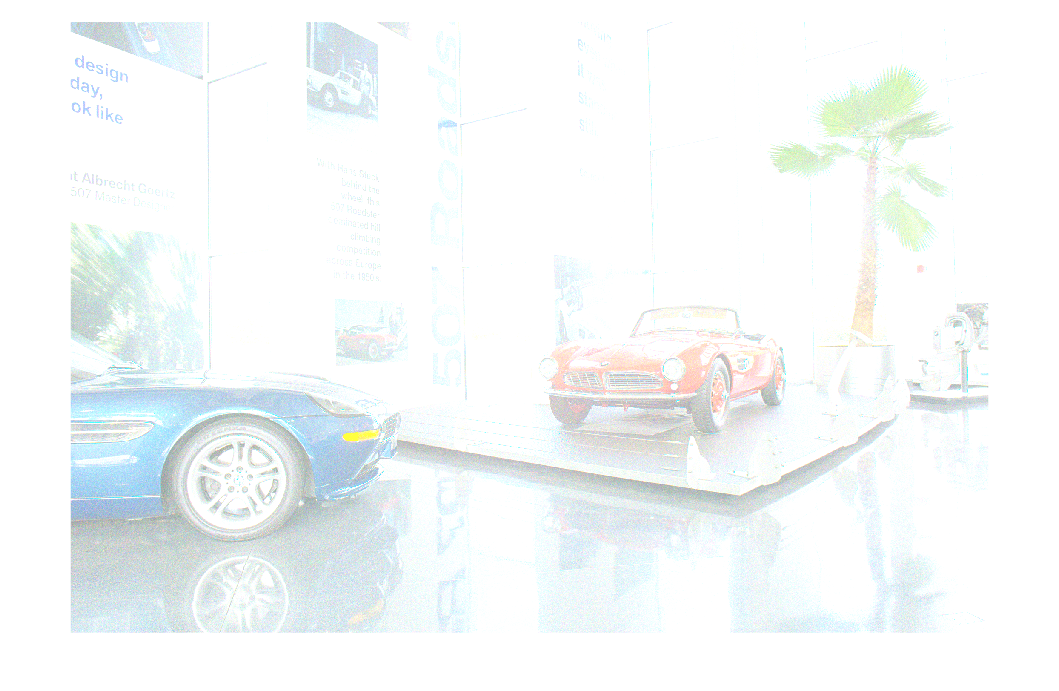

RGB = tonemapfarbman(HDR);
imshow(RGB)